% Import October temperatures per hour
outdoorTemperatures = table2array(readtable('smhi-opendata_1_97200_20240125_095312.csv', Range="C334:C1056"));

**Standard Thermostat**

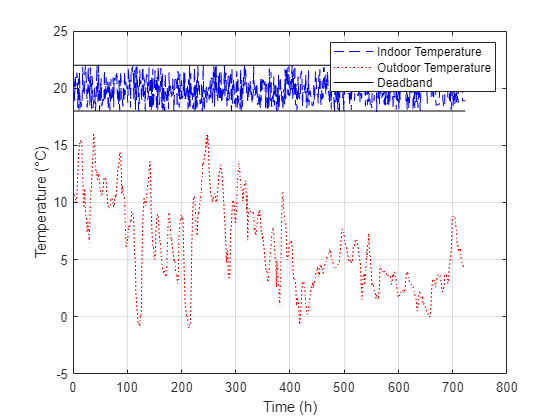

deadBand = 2;
action = 0;
setPointTemperature = 20;
roomTemperature = 20;
t= 3600;
thermal_resistance = 0.0015;

% Flow rate = 3600kg/h
Mdot = 3600;
% heat capacity, in celsius
c = 1005.4;
% energy cost rate
costPerJoule = 0.09;

% Volume of the room in cubic meters
room_volume = 100; 
% Density of air in kg/m^3
air_density = 1.225;

% Calculate mass of air in the room
mAir = air_density * room_volume;

totalCosts = zeros(size(outdoorTemperatures));
totalCost = 0;
roomTemperatures = zeros(size(outdoorTemperatures));

for i=1:size(outdoorTemperatures)
    [heatCost, roomTemperature] = StepSimulation(outdoorTemperatures(i), roomTemperature, setPointTemperature, deadBand, mAir, action, Mdot, c, t, thermal_resistance, costPerJoule);
    totalCost = totalCost + heatCost;
    totalCosts(i) = totalCost;
    roomTemperatures(i) = roomTemperature;
end

x = zeros(size(outdoorTemperatures));
lowerBounds = zeros(size(outdoorTemperatures));
upperBounds = zeros(size(outdoorTemperatures));
totalX = 0;
for i=1:size(x)
    x(i) = totalX + 1;
    totalX = totalX + 1;
    lowerBounds(i) = setPointTemperature-deadBand;
    upperBounds(i) = setPointTemperature+deadBand;
end

plot(x, roomTemperatures, 'b--', x, outdoorTemperatures, 'r:', x, lowerBounds, 'k', x, upperBounds, 'k');
xlabel('Time (h)')
ylabel('Temperature (°C)')
legend('Indoor Temperature', 'Outdoor Temperature', 'Deadband');
grid on;

**Simulation**

function [heatCost, roomTemperature] = StepSimulation(outdoorTemperature, roomTemperature, setPointTemperature, deadBand, mAir, action, Mdot, c, t, thermal_resistance, costPerJoule)
heatCost = 0;

for i=1:t
heatFlow = Heater(roomTemperature, 50, action, 1, c);
tempDiff = House(heatFlow, roomTemperature, outdoorTemperature, thermal_resistance, mAir, c);
roomTemperature = roomTemperature + tempDiff;
heatCost = heatCost + CostCalculator(heatFlow, costPerJoule);

diff = roomTemperature - setPointTemperature;
    if abs(diff) > deadBand
        if diff > 0
            action = 0;
        else 
            action = 1;
        end
    end

end

heatCost = heatCost / 3.6e6;
end